# Start End Marker

Marks the doy of start and end of disturbance.

For faster performance.

## I / O

clear
clc
% Choose mask file.
[File, Path]=uigetfile({'*.tif'},'Choose mask file.','Multiselect','off','/home/dk/文档/Tutor/localSTMoran/其他数据与资料/');
[mask, R0] = geotiffread(strcat(Path, File));
[x,y] = size(mask);

% Counter image.
distCounterImg = zeros(x,y);
tempCounter = zeros(x,y);

% Choose time series imagery.
[file, path] = uigetfile({'*.tif'}, 'Choose imagery.', 'Multiselect', 'on', '/home/dk/文档/Tutor/localSTMoran/(第二次挑选）衡阳盆地Landsat一致性数据生成结果/image/');
[~, fileLength] = size(file);

% Output directory
selected_dir = uigetdir('/home/dk/文档/Tutor/localSTMoran/(第二次挑选）衡阳盆地Landsat一致性数据生成结果/image/distStart/','Disturbance time output');


tic
% Read & mask time series images and batch NDVI.
sDate = nan(x,y);
f = waitbar(0,'Start marker initializing.')

f =   Figure (TMWWaitbar) - 属性:

      Number: []
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [585 376.8750 270 56.2500]
       Units: 'points'

  显示 所有属性


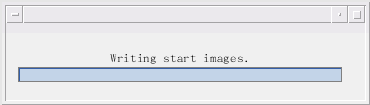

for counter = 1:14
    startMarker = nan(x,y);
    counterIM = zeros(x,y);
    if counter ~= 1
        counterIM = zeros(x,y);
        for i = 1:counter-1
            formerMarker = geotiffread(strcat(selected_dir,'/distStart',num2str(i), '.tif'));
            counterIM = counterIM + formerMarker;
        end
    end
    
    for num = 2:fileLength-1
        prevIM = geotiffread(strcat(path,char(file(num-1))));
        currentIM = geotiffread(strcat(path,char(file(num))));
        nextIM = geotiffread(strcat(path,char(file(num+1))));
        
        DOYtemp = char(file(num));
        DOYtemp = DOYtemp(1:end-4);
        doy = doyDiff(1987000,str2num(DOYtemp));
        
        startMarker(prevIM == 0 & currentIM == 1 & nextIM == 1 & isnan(startMarker) & counterIM == (counter - 1)) = doy;
      
%         endMarker(prevIM == 1 & currentIM == 0 & isnan(endMarker)) = doy;
%         geotiffwrite(strcat(selected_dir,'/distEnd',num2str(counter)),endMarker,R0,'CoordRefSysCode',32649);
        
    %     geotiffwrite(strcat(selected_dir,'/distStart_',DOYtemp),sDate,R0,'CoordRefSysCode',32649);
    end
    waitbar(counter / 14,f,'Writing start images.');
    geotiffwrite(strcat(selected_dir,'/distStart',num2str(counter)),startMarker,R0,'CoordRefSysCode',32649);
    clear startMarker;
    
end

toc

时间已过 1739.938454 秒。



clear prevIM currentIM nextIM startMarker;

tic
f = waitbar(0,'End marker initializing.')

f =   Figure (TMWWaitbar) - 属性:

      Number: []
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [585 376.8750 270 56.2500]
       Units: 'points'

  显示 所有属性


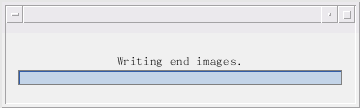

for counter = 1:14
    endMarker = nan(x,y);
    for num = 2:fileLength-1      % Search for the whole series.
        prevIM = geotiffread(strcat(path,char(file(num-1))));
        currentIM = geotiffread(strcat(path,char(file(num))));
        nextIM = geotiffread(strcat(path,char(file(num))));
        startMarker = geotiffread(strcat(selected_dir,'/distStart',num2str(counter)));
        
        DOYtemp = char(file(num-1));
        DOYtemp = DOYtemp(1:end-4);
        doy = doyDiff(1987000,str2num(DOYtemp));
        

        endMarker(prevIM == 1 & currentIM == 0 & nextIM == 0 & isnan(endMarker)) = doy;
        endMarker(endMarker<= startMarker) = nan;   % Disturbance should end later than start.
    end
    waitbar(counter / 14,f,'Writing end images.');
    geotiffwrite(strcat(selected_dir,'/distEnd',num2str(counter)),endMarker,R0,'CoordRefSysCode',32649);
end

toc

时间已过 2427.831218 秒。



% geotiffwrite('/home/dk/文档/Tutor/localSTMoran/(第二次挑选）衡阳盆地Landsat一致性数据生成结果/distCounter.tif',distCounterImg,R0,'CoordRefSysCode',32649)
